data1 = open_and_importdata('F:\論文\1080911\full\擬合平面')

data1 =     0.2034    0.3785    1.7531
    0.1976    0.3795    1.7243
    0.1967    0.3795    1.0466
    0.2723    0.3800    1.0995
    0.2675    0.3810    1.0560
    0.2680    0.3810    1.0702
    0.2501    0.3696    1.0350
    0.2164    0.3610    1.0427
    0.2699    0.3805    1.0848
    0.2678    0.3810    1.1278


data2 = open_and_importdata('F:\論文\1080911\full\擬合平面')

data2 =     0.4171    0.4402    1.0036
    0.4154    0.4119    1.0051
    0.4084    0.4860    1.2248
    0.4144    0.6013    1.0329
    0.4144    0.6013    1.0183
    0.4179    0.5862    1.0305
    0.4158    0.6013    1.0471
    0.4123    0.6018    1.0612
    0.4139    0.5867    1.0588
    0.4140    0.5867    1.0446


data3 = open_and_importdata('F:\論文\1080911\full\擬合平面')

data3 =     0.3647    0.6305    1.5309
    0.3629    0.6313    1.5236
    0.3643    0.6308    1.5158
    0.3655    0.6299    1.5084
    0.3654    0.6299    1.5607
    0.3654    0.6299    1.5460
    0.3621    0.6320    1.5387
    0.3643    0.6308    1.5534
    0.2409    0.6325    1.5277
    0.3170    0.6316    1.5303


data4 = open_and_importdata('F:\論文\1080911\full\擬合平面')

data4 =     0.1578    0.5122    1.0597
    0.1599    0.5364    1.0426
    0.1593    0.5110    1.0446
    0.1583    0.5206    1.0490
    0.1582    0.5290    1.0460
    0.1557    0.5221    1.0421
    0.1594    0.5367    1.0573
    0.1605    0.5365    1.0500
    0.1616    0.5355    1.0646
    0.1598    0.5194    1.0636



x1 = data1(:,1);
y1 = data1(:,2);
z1 = data1(:,3);

x2 = data2(:,1);
y2 = data2(:,2);
z2 = data2(:,3);

x3 = data3(:,1);
y3 = data3(:,2);
z3 = data3(:,3);

x4 = data4(:,1);
y4 = data4(:,2);
z4 = data4(:,3);
%%%第一面
sf1 = fit([x1, y1],z1,'poly11');

coefficientValuesA = coeffvalues(sf1);
x0=0.15,L1=0.27;

x0 = 0.1500

z0=0.85,L2=2.6;

z0 = 0.8500

x=x0+rand(10000,1)*L1;
z=z0+rand(10000,1)*L2;
c =coefficientValuesA(1,1);
x_coefficient=coefficientValuesA(1,2);
y_coefficient = coefficientValuesA(1,3)

y_coefficient = -139.0398

y = -((x_coefficient)/y_coefficient).*x+(z/y_coefficient)-(c/y_coefficient);
figure(1)
scatter3(x,y,z,'.');
axis equal
hold on
surfaceA =[x_coefficient y_coefficient -1] 

surfaceA =    -0.9385 -139.0398   -1.0000


%%%第二面
sf2 = fit([x2, y2],z2,'poly11');

coefficientValuesB = coeffvalues(sf2);
y0=0.37,L1=0.28;

y0 = 0.3700

z0=0.85,L2=2.6;

z0 = 0.8500

z=z0+rand(10000,1)*L2;
y=y0+rand(10000,1)*L1;
c =coefficientValuesB(1,1);
x_coefficient=coefficientValuesB(1,2);
y_coefficient = coefficientValuesB(1,3)

y_coefficient = 1.4091

x = -(y_coefficient/x_coefficient).*y+(z/x_coefficient)-(c/x_coefficient)

x =     0.4064
    0.4150
    0.4182
    0.4164
    0.4015
    0.3980
    0.4158
    0.4169
    0.4096
    0.4202


figure(1)
scatter3(x,y,z,'.');
hold on
surfaceB =[x_coefficient y_coefficient -1] 

surfaceB =   -99.4333    1.4091   -1.0000


%%%第三面
sf3 = fit([x3, y3],z3,'poly11');

x0=0.15,L1=0.27;

x0 = 0.1500

z0=0.85,L2=2.6;

z0 = 0.8500

coefficientValuesC = coeffvalues(sf3);
x=x0+rand(10000,1)*L1;
z=z0+rand(10000,1)*L2;
c =coefficientValuesC(1,1);
x_coefficient=coefficientValuesC(1,2);
y_coefficient = coefficientValuesC(1,3)

y_coefficient = -111.6774

y = -((x_coefficient)/y_coefficient).*x+(z/y_coefficient)-(c/y_coefficient);
figure(1)
scatter3(x,y,z,'.');
hold on
surfaceC =[x_coefficient y_coefficient -1] 

surfaceC =    -0.8257 -111.6774   -1.0000


%%%第四面
sf4 = fit([x4, y4],z4,'poly11');


coefficientValuesD= coeffvalues(sf4);
y0=0.37,L1=0.28;

y0 = 0.3700

z0=0.85,L2=2.6;

z0 = 0.8500

z=z0+rand(10000,1)*L2;
y=y0+rand(10000,1)*L1;
c =coefficientValuesD(1,1);
x_coefficient=coefficientValuesD(1,2);
y_coefficient = coefficientValuesD(1,3)

y_coefficient = 2.6311

x = -(y_coefficient/x_coefficient).*y+(z/x_coefficient)-(c/x_coefficient)

x =     0.1603
    0.1640
    0.1532
    0.1602
    0.1613
    0.1617
    0.1550
    0.1582
    0.1565
    0.1579


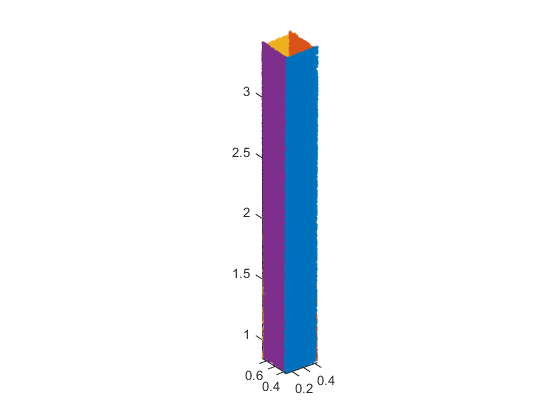


figure(1)
scatter3(x,y,z,'.');
axis equal
hold off

surfaceD =[x_coefficient y_coefficient -1] 

surfaceD =  -179.4679    2.6311   -1.0000


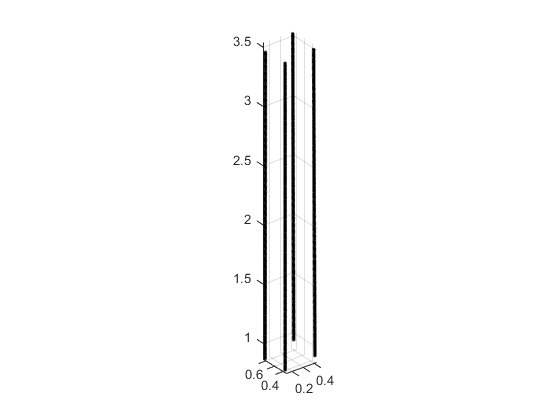



%%畫出交線


poly_data_1 = zeros(261,3);
poly_data_2 = zeros(261,3);
poly_data_3 = zeros(261,3);
poly_data_4 = zeros(261,3);

c1= cross(surfaceA,surfaceB);
x_vector = c1(1)/c1(3);
y_vector = c1(2)/c1(3);

line=1;
for i =0:0.01:2.6
    
x = 0.42094+x_vector.*i;
y = 0.37409+y_vector.*i;
z = 0.92055+i;

poly_data_1(line,1) = x;
poly_data_1(line,2) = y;
poly_data_1(line,3) = z;

figure(2)
scatter3(x,y,z,'.','k')
axis equal
hold on
line=line+1;
end

c2= cross(surfaceB,surfaceC);
x_vector = c2(1)/c2(3);
y_vector = c2(2)/c2(3);

line=1;

for j =0:0.01:2.6
x =0.41601+x_vector.*j;
y =0.6226+y_vector.*j;
z =0.94199+j;

figure(2)
scatter3(x,y,z,'.','k')
axis equal
hold on
poly_data_2(line,1)=x;
poly_data_2(line,2)=y;
poly_data_2(line,3)=z;

line=line+1;
end

c3= cross(surfaceC,surfaceD);
x_vector = c3(1)/c3(3);
y_vector = c3(2)/c3(3);

line=1;
for k =0:0.01:2.6
x =0.15935+x_vector.*k;
y =0.63105+y_vector.*k;
z =0.86977+k;

figure(2)
scatter3(x,y,z,'.','k')
axis equal
hold on
poly_data_3(line,1)=x;
poly_data_3(line,2)=y;
poly_data_3(line,3)=z;

line=line+1;

end

c4= cross(surfaceD,surfaceA);
x_vector = c4(1)/c4(3);
y_vector = c4(2)/c4(3);


line=1;
for l =0:1:260
x =0.15973+x_vector.*l*0.01;
y =0.3906+y_vector.*l*0.01;
z =0.88442+l*0.01;

figure(2)
scatter3(x,y,z,'.','k')
axis equal
hold on
poly_data_4(line,1)=x;
poly_data_4(line,2)=y;
poly_data_4(line,3)=z;

line=line+1;
end


xlswrite('F:\論文\1080911\full\擬合平面\C1\edge1.xlsx',poly_data_1)
xlswrite('F:\論文\1080911\full\擬合平面\C1\edge2.xlsx',poly_data_2)
xlswrite('F:\論文\1080911\full\擬合平面\C1\edge3.xlsx',poly_data_3)
xlswrite('F:\論文\1080911\full\擬合平面\C1\edge4.xlsx',poly_data_4)
